# **Licence Plate Recognition**

**Design of Visual Systems Final Project **

*Clemence Sulmont & Ciara Bates* 

**Section 1 : Open Image and cropping / rotation**

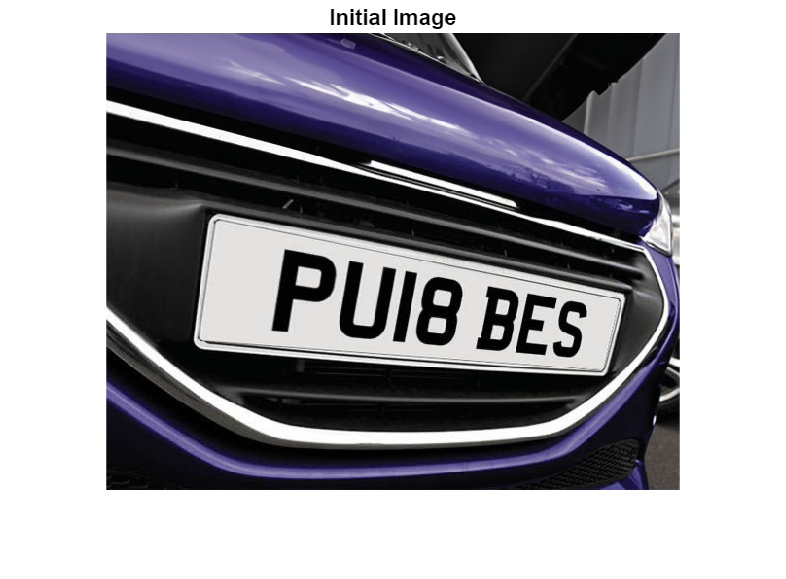

% Clear workspace
clear; clc;

% Load and show the image of the front of a car
f = imread("car_img/cars4.png");
imshow(f)
title('Initial Image');

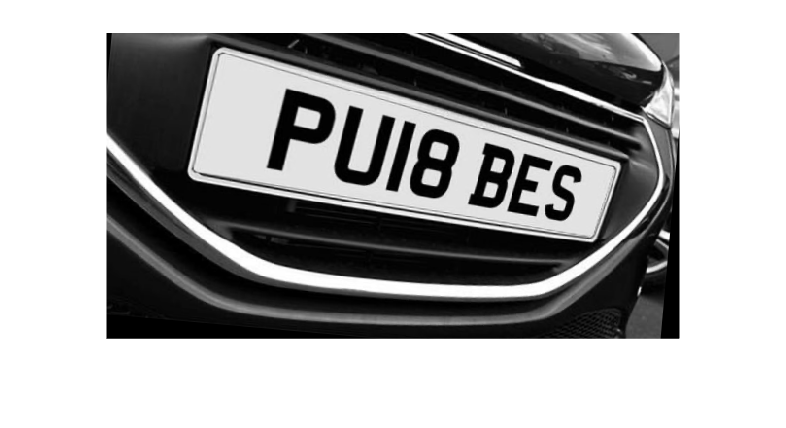

% The image must be greyscale for all processing, thsi also makes the code run
% faster as each pixel has only 1 intensity value rather than colour information. 
img = im2double(rgb2gray(f)); 

% The image must be rotated slightly for the corner recognition function
% less likely to find corners that are in the exact same row and/or column
img = imrotate(img, -5, 'bilinear', 'crop');

% Removing (cropping) the top third of the image (windshield area)
[height,width, numChannels] = size(img);
startrow = floor(height/3) + 1;
img = img(startrow:end, :, :);
imshow(img)

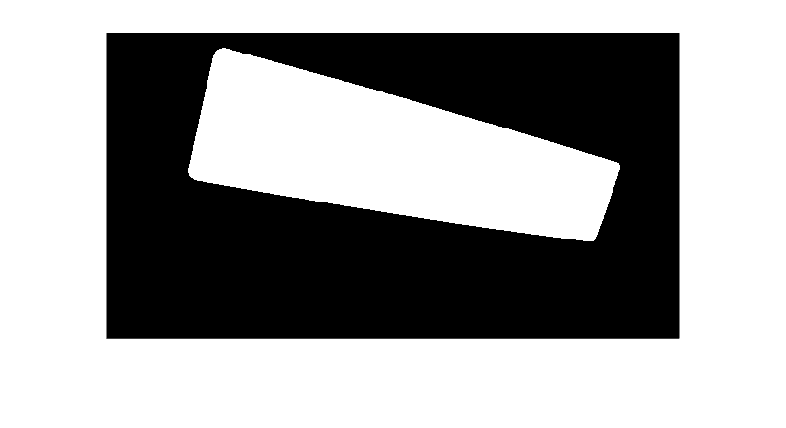

fourcorners = 4×2 single matrix
  121.4501   15.8003
  528.9343  136.0657
  502.9395  213.0000
   85.0113  142.0113


output = getCornersLicense(img);

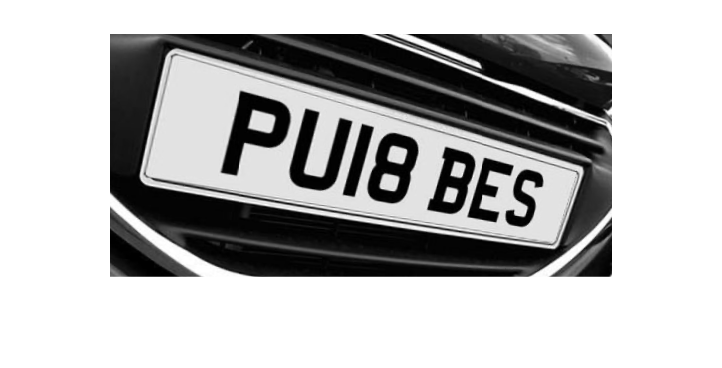

min_x = floor(min(output(:, 1)));
max_x = floor(max(output(:, 1)));
min_y = floor(min(output(:, 2)));
max_y = floor(max(output(:, 2)));

padding = 30;

% Construct the rectangle vector for cropping an image
RECT_original = [min_x-padding, min_y - padding, max_x - min_x + padding*2, max_y - min_y + padding*2];

cropped_1 = imcrop(img,RECT_original);
imshow(cropped_1)

**Section 2 : Homography Transform **

fourcorners = 4×2 single matrix
  121.4501   15.8003
  528.9343  136.0657
  502.9395  213.0000
   85.0113  142.0113


% Get 4 input points for the homography transform
output = getCornersLicense(img);

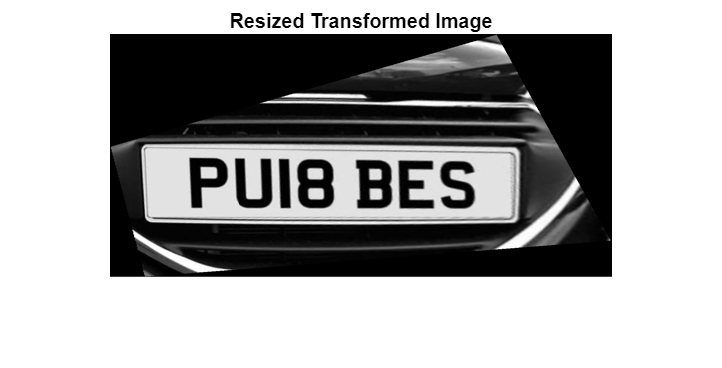

xi = output(:,1);
yi = output(:,2);

% Define the base points for the transformation
base = [1 1; 1 size(cropped_1, 1); size(cropped_1, 2) 1; size(cropped_1, 2) size(cropped_1, 1);];


% Compute the homography transform
tf = fitgeotrans([xi, yi], base, 'projective');
H = tf.T;

% Perform the homography transformation
[xf, xf_ref] = imwarp(cropped_1, tf);


% Specify the desired width and height of the output image (in pixels)
desired_width = size(cropped_1, 2);
desired_height = size(cropped_1, 1);

% Resize the output image while maintaining its aspect ratio
xf_resized = imresize(xf, [desired_height, desired_width]);

% Display the resized transformed image
figure;
imshow(xf_resized);
hold on;
title('Resized Transformed Image');

**Section 3 : Cropping the image (again)**

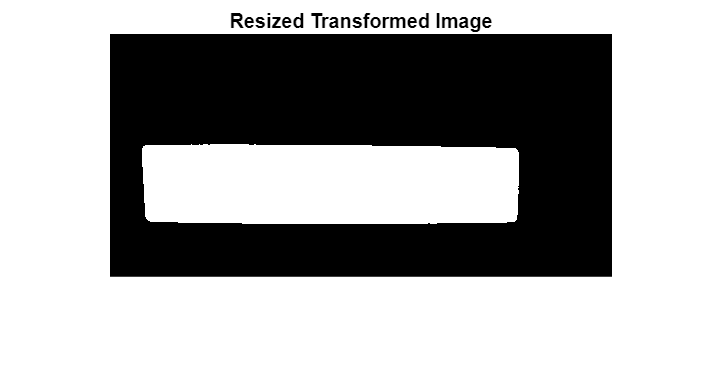

fourcorners = 4×2 single matrix
  146.5623  110.9377
  411.5000  154.5000
  320.5524  190.2095
   33.2493  114.7507


corners = getCornersLicense(xf_resized);

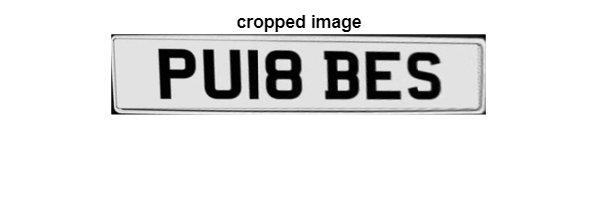


min_x = floor(min(corners(:, 1)));
max_x = floor(max(corners(:, 1)));
min_y = floor(min(corners(:, 2)));
max_y = floor(max(corners(:, 2)));

% Construct the rectangle vector for cropping an image
RECT = [min_x, min_y, max_x - min_x, max_y - min_y];

cropped = imcrop(xf_resized,RECT);

figure
imshow(cropped)
title('cropped image')

**Section 4 : Segmenting Letters using MSER regions**

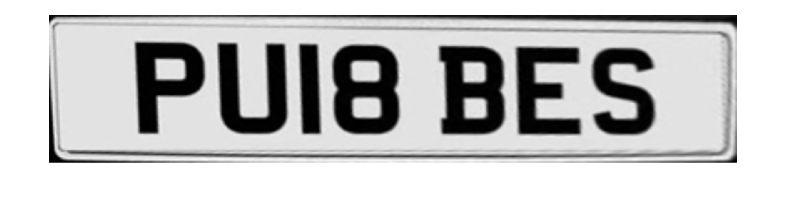


I = imresize(cropped,[500 NaN]); %resize so the number of rows of pixels is 500. 
%The number of columns is automatically calculated based on aspect ratio

imshow(I)

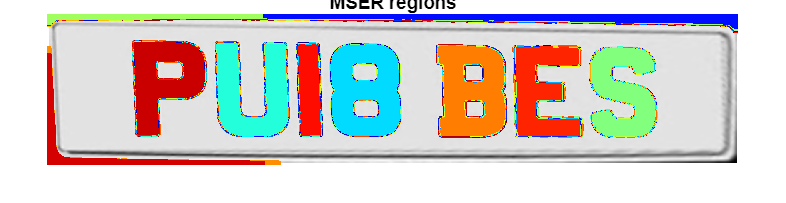


% Detect MSER regions. 
[mserRegions, mserConnComp] = detectMSERFeatures(I, ... 
    "RegionAreaRange",[10000 60000],"ThresholdDelta",5);

figure
imshow(I)
hold on
plot(mserRegions, "showPixelList", true,"showEllipses",false)
title("MSER regions")
hold off

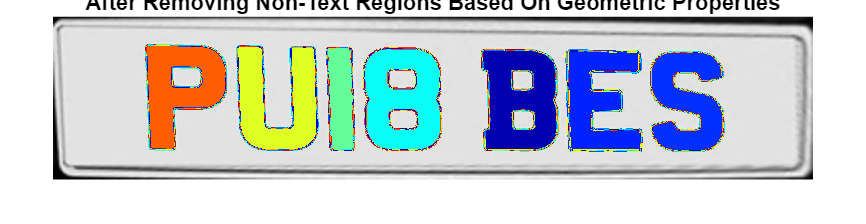


% Use regionprops (region properties) to measure MSER properties
mserStats = regionprops(mserConnComp, "BoundingBox", "Eccentricity", ...
    "Solidity", "Extent", "Euler", "Image");

% Compute the aspect ratio using bounding box data.
bbox = vertcat(mserStats.BoundingBox);
w = bbox(:,3);
h = bbox(:,4);
aspectRatio = w./h;

% Threshold the data to determine which regions to remove. These thresholds
% may need to be tuned for other images.
filterIdx = aspectRatio' > 3; 
filterIdx = filterIdx | [mserStats.Eccentricity] > .995 ;
filterIdx = filterIdx | [mserStats.Solidity] < .3;
filterIdx = filterIdx | [mserStats.Extent] < 0.2 | [mserStats.Extent] > 0.9;
filterIdx = filterIdx | [mserStats.EulerNumber] < -4;

% Remove regions
mserStats(filterIdx) = [];
mserRegions(filterIdx) = [];

% Show remaining regions
figure
imshow(I)
hold on
plot(mserRegions, "showPixelList", true,"showEllipses",false)
title("After Removing Non-Text Regions Based On Geometric Properties")
hold off

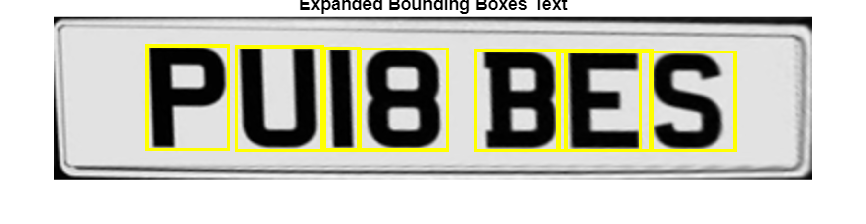


% --------- Create and Show the Bounding Boxes ---------- %

% Get bounding boxes for all the regions
bboxes = vertcat(mserStats.BoundingBox);

% Convert from the [x y width height] bounding box format to the [xmin ymin
% xmax ymax] format for convenience.
xmin = bboxes(:,1);
ymin = bboxes(:,2);
xmax = xmin + bboxes(:,3) - 1;
ymax = ymin + bboxes(:,4) - 1;

% Expand the bounding boxes by a small amount.
expansionAmount = 0.02;
xmin = (1-expansionAmount) * xmin;
ymin = (1-expansionAmount) * ymin;
xmax = (1+expansionAmount) * xmax;
ymax = (1+expansionAmount) * ymax;

% Clip the bounding boxes to be within the image bounds
xmin = max(xmin, 1);
ymin = max(ymin, 1);
xmax = min(xmax, size(I,2));
ymax = min(ymax, size(I,1));

% Show the expanded bounding boxes
expandedBBoxes = [xmin ymin xmax-xmin+1 ymax-ymin+1];
IExpandedBBoxes = insertShape(I,"rectangle",expandedBBoxes,"LineWidth",3);

figure
imshow(IExpandedBBoxes)
title("Expanded Bounding Boxes Text")

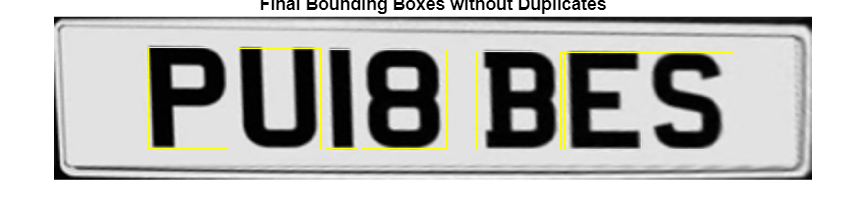


% --------- Removing Overlapping Bounding Boxes ---------- %

% Initialize an empty array to store indices of unique bounding boxes
uniqueIndices = [];

% Calculate the area of each bounding box
areas = (xmax - xmin + 1) .* (ymax - ymin + 1);

% Iterate over each bounding box
for i = 1:size(expandedBBoxes, 1)
    % Flag to indicate if current bounding box is unique
    isUnique = true;
    
    % Iterate over already identified unique bounding boxes
    for j = 1:length(uniqueIndices)
        % Calculate intersection area
        x_overlap = max(0, min(xmax(i), xmax(uniqueIndices(j))) - max(xmin(i), xmin(uniqueIndices(j))));
        y_overlap = max(0, min(ymax(i), ymax(uniqueIndices(j))) - max(ymin(i), ymin(uniqueIndices(j))));
        intersection_area = x_overlap * y_overlap;
        
        % Calculate area ratio (intersection over min area)
        area_ratio = intersection_area / min(areas(i), areas(uniqueIndices(j)));
        
        % If area ratio is above a threshold, consider the bounding box duplicate
        if area_ratio > 0.5 % Adjust threshold as needed
            isUnique = false;
            break;
        end
    end
    
    % If current bounding box is unique, add its index to uniqueIndices
    if isUnique
        uniqueIndices = [uniqueIndices, i];
    end
end

% Extract unique bounding boxes
uniqueBBoxes = expandedBBoxes(uniqueIndices, :);

% Show the final bounding boxes after removing duplicates
IFinalBBoxes = insertShape(I, "rectangle", uniqueBBoxes, "LineWidth", 3);

figure
imshow(IFinalBBoxes)
title("Final Bounding Boxes without Duplicates")

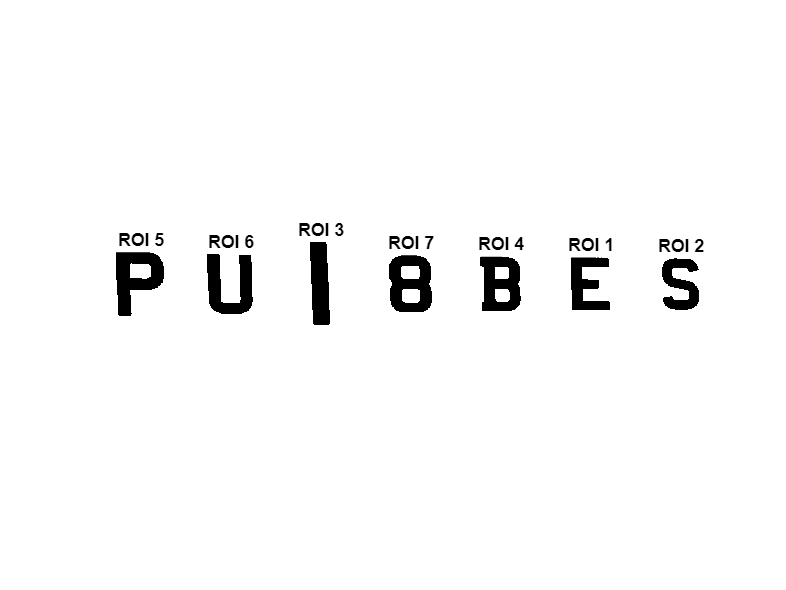


% ---------------- Creating ROI images from Bounding Boxes ------------- %

% Initialize cell array to store individual letter ROIs and their corresponding bounding boxes
letterROIs = cell(size(uniqueBBoxes, 1), 1);
orderedBBoxes = uniqueBBoxes; % Copy bounding boxes for sorting

% Sort bounding boxes by their x-coordinates (xmin) This is so they are
% read and displayed in the correct order
[~, order] = sort(orderedBBoxes(:, 1));
orderedBBoxes = orderedBBoxes(order, :);

% Iterate over each bounding box
for i = 1:size(orderedBBoxes, 1)
    % Extract ROI using bounding box coordinates
    xmin = orderedBBoxes(i, 1);
    ymin = orderedBBoxes(i, 2);
    width = orderedBBoxes(i, 3);
    height = orderedBBoxes(i, 4);
    roi = imcrop(I, [xmin, ymin, width, height]);
    
    roi = imresize(roi,[100,NaN]); % resize the image to height 400px
    roi = imbinarize(roi); % Binarize the image
   
    
    % Define the desired dimensions for the resized image
    desired_height = 80;
    desired_width = 60; 

    % Calculate the padding amounts for each side
    pad_height = max(0, desired_height - size(roi, 1));
    pad_width = max(0, desired_width - size(roi, 2));
    pad_top = floor(pad_height / 2);
    pad_bottom = ceil(pad_height / 2);
    pad_left = floor(pad_width / 2);
    pad_right = ceil(pad_width / 2);

    % Pad the image evenly around the whole image with ones
    padded_image = padarray(roi, [pad_top, pad_left], 1, 'pre');
    padded_image = padarray(padded_image, [pad_bottom, pad_right], 1, 'post');
    
    %padded_image = imresize(padded_image,[200,150]); %ensuring the image size is correct
    
    clean_letter = imcomplement(padded_image);
    CC = bwconncomp(clean_letter);
    numpixels = cellfun(@numel, CC.PixelIdxList);
    [biggest, idx] = max(numpixels);
    
    for k = 1:length(numpixels)
        if k~= idx
            clean_letter(CC.PixelIdxList{k}) = 0;
        end
    end
    
    % Store preprocessed ROI
    letterROIs{i} = imcomplement(clean_letter);
    
end

figure;

% Display each ROI in a subplot, in order of when they appear in the image
% (left to right)
for i = 1:length(letterROIs)
    
    % Create subplot with adjusted aspect ratio
    subplot(1, length(letterROIs), i);
    
    % Display ROI
    imshow(letterROIs{i})

    % Set title
    title(['ROI ' num2str(order(i))]); % Display original order
end

**Section 5 :  Detecting Letters using MATLAB's OCR function **

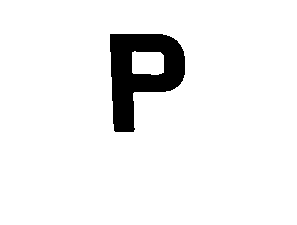

  ocrText with properties:

                      Text: 'P'
    CharacterBoundingBoxes: [1 1 79 100]
      CharacterConfidences: 0.9632
                     Words: {'P'}
         WordBoundingBoxes: [1 1 79 100]
           WordConfidences: 0.7423
                 TextLines: {'P'}
     TextLineBoundingBoxes: [1 1 79 100]
       TextLineConfidences: 0.7423



licence_plate_ocr = "P"

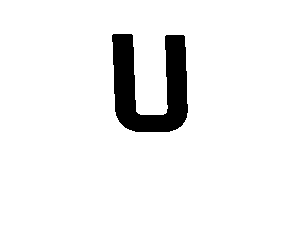

  ocrText with properties:

                      Text: 'U'
    CharacterBoundingBoxes: [1 1 84 100]
      CharacterConfidences: 0.9595
                     Words: {'U'}
         WordBoundingBoxes: [1 1 84 100]
           WordConfidences: 0.7167
                 TextLines: {'U'}
     TextLineBoundingBoxes: [1 1 84 100]
       TextLineConfidences: 0.7167



licence_plate_ocr = "PU"

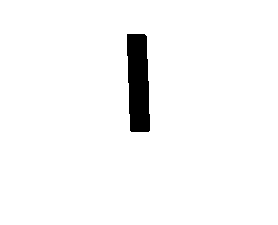

  ocrText with properties:

                      Text: 'l'
    CharacterBoundingBoxes: [19 1 21 98]
      CharacterConfidences: 0.8226
                     Words: {'l'}
         WordBoundingBoxes: [19 1 21 98]
           WordConfidences: 0
                 TextLines: {'l'}
     TextLineBoundingBoxes: [19 1 21 98]
       TextLineConfidences: 0



licence_plate_ocr = "PUl"

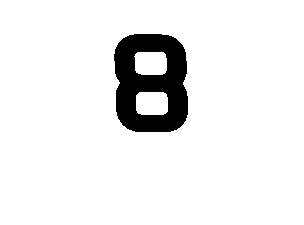

  ocrText with properties:

                      Text: '8'
    CharacterBoundingBoxes: [1 1 86 100]
      CharacterConfidences: 0.9868
                     Words: {'8'}
         WordBoundingBoxes: [1 1 86 100]
           WordConfidences: 0.9079
                 TextLines: {'8'}
     TextLineBoundingBoxes: [1 1 86 100]
       TextLineConfidences: 0.9079



licence_plate_ocr = "PUl8"

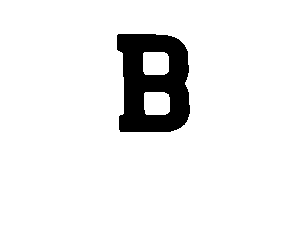

  ocrText with properties:

                      Text: 'B'
    CharacterBoundingBoxes: [1 1 90 100]
      CharacterConfidences: 0.9886
                     Words: {'B'}
         WordBoundingBoxes: [1 1 90 100]
           WordConfidences: 0.9200
                 TextLines: {'B'}
     TextLineBoundingBoxes: [1 1 90 100]
       TextLineConfidences: 0.9200



licence_plate_ocr = "PUl8B"

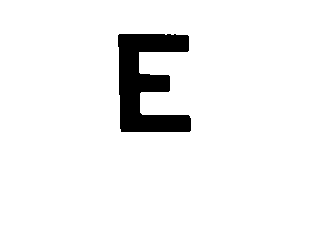

  ocrText with properties:

                      Text: 'E'
    CharacterBoundingBoxes: [10 1 73 98]
      CharacterConfidences: 0.9635
                     Words: {'E'}
         WordBoundingBoxes: [10 1 73 98]
           WordConfidences: 0.7445
                 TextLines: {'E'}
     TextLineBoundingBoxes: [10 1 73 98]
       TextLineConfidences: 0.7445



licence_plate_ocr = "PUl8BE"

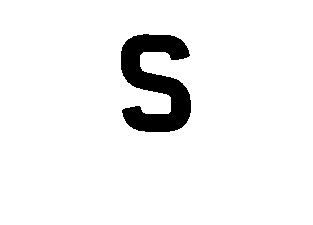

  ocrText with properties:

                      Text: 'S'
    CharacterBoundingBoxes: [13 1 70 98]
      CharacterConfidences: 0.9876
                     Words: {'S'}
         WordBoundingBoxes: [13 1 70 98]
           WordConfidences: 0.9135
                 TextLines: {'S'}
     TextLineBoundingBoxes: [13 1 70 98]
       TextLineConfidences: 0.9135



licence_plate_ocr = "PUl8BES"

% Apply OCR
licence_plate_ocr = "";

for i = 1:length(letterROIs)
    
    letter = letterROIs{i};
    
    figure
    imshow(letter)
    
    results = ocr(letter, 'TextLayout', 'Character','CharacterSet','ABCDEFGHIJKLMNOPQRSTUVWXYZ1234567890l#');
    disp(results)
    licence_plate_ocr = licence_plate_ocr + results.Text
    
end


disp('License number = ')

License number = 


disp(licence_plate_ocr)

PUl8BES


**Section 6 : Detecting letters using similarity **

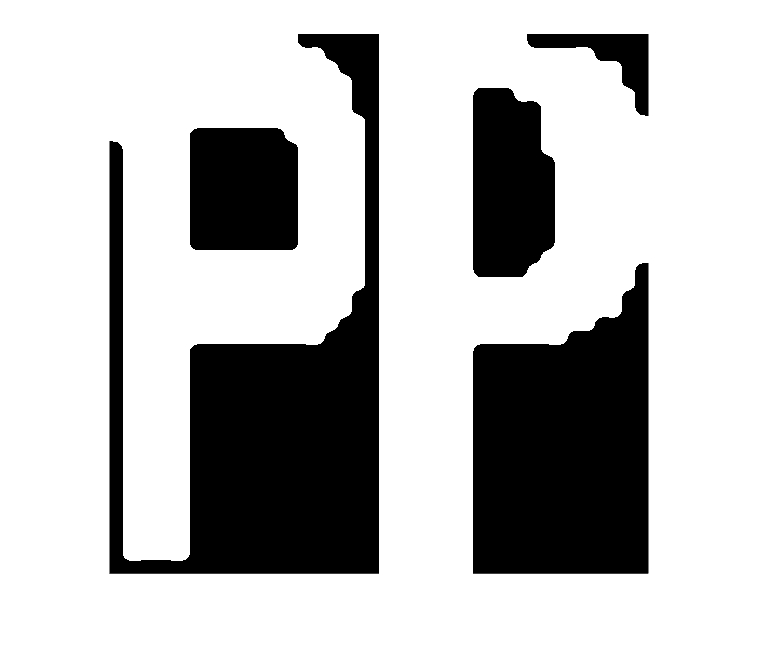

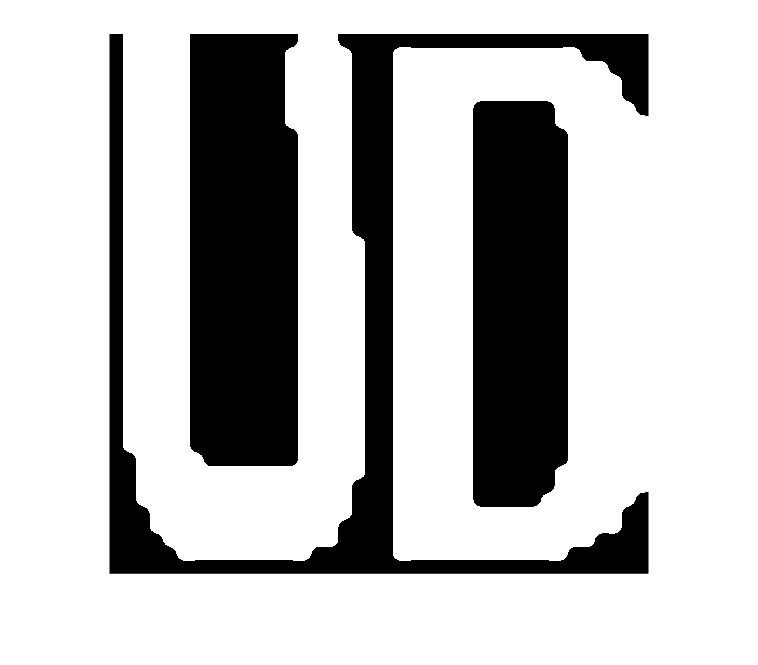

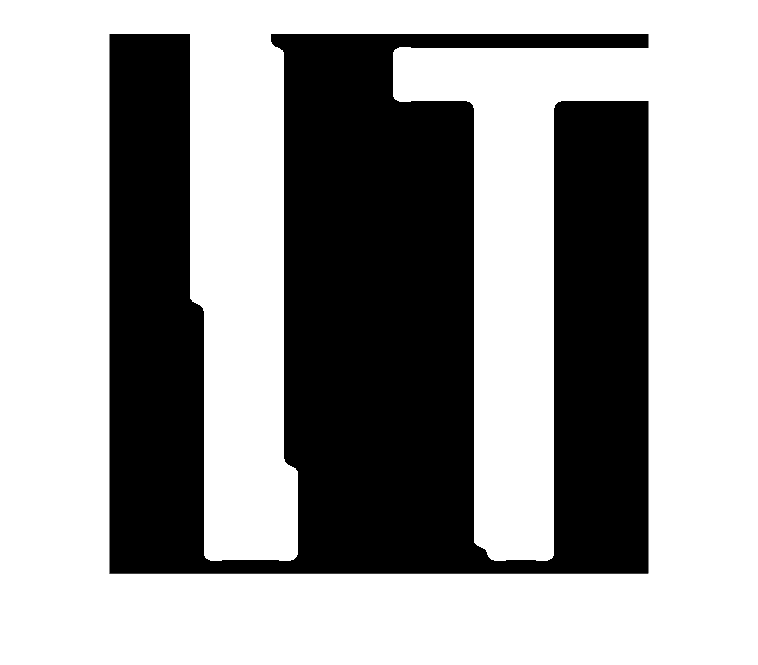

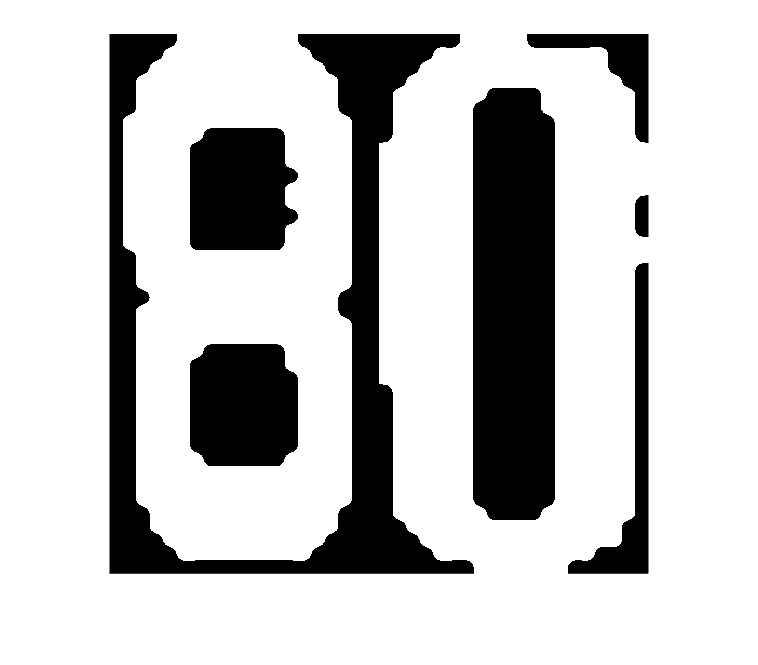

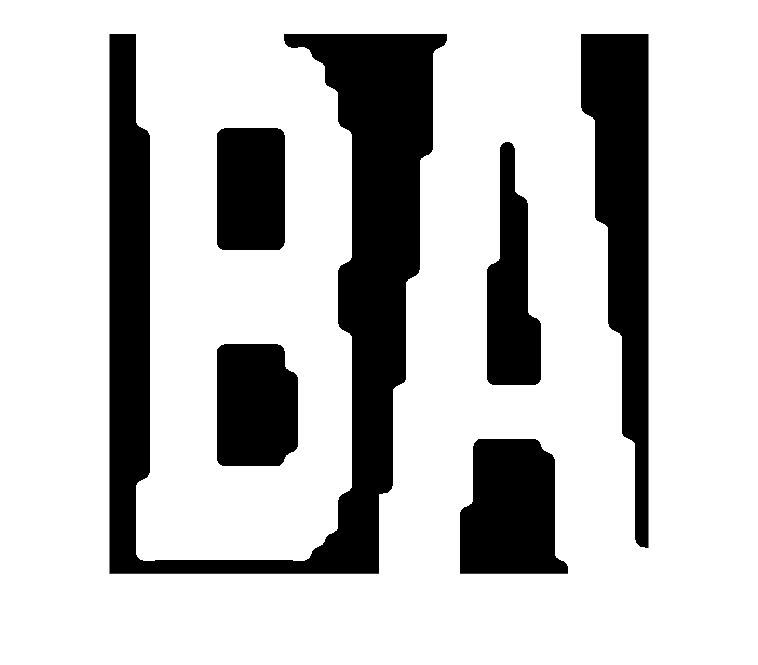

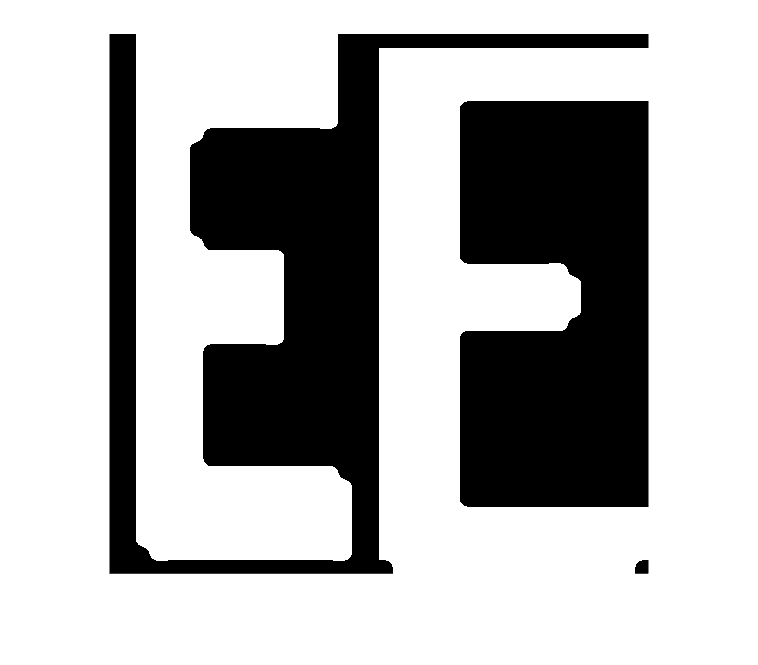

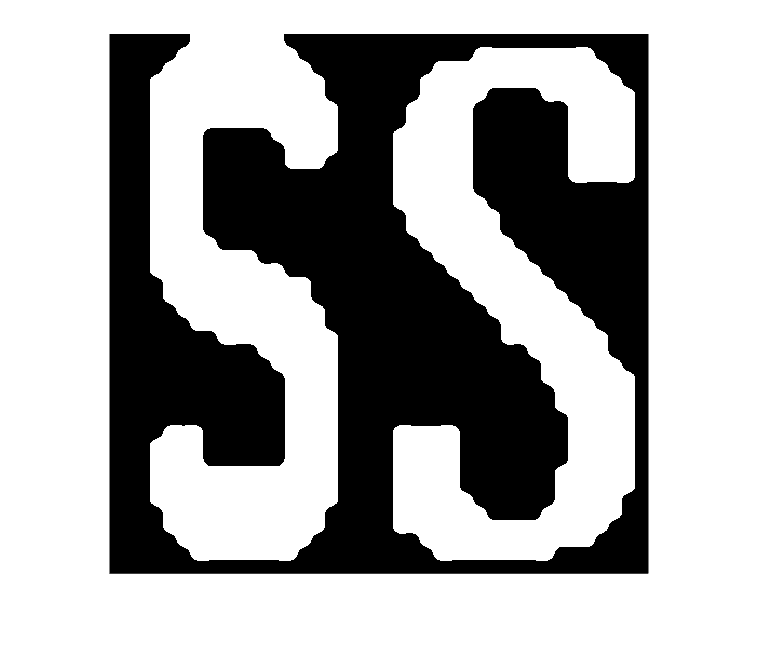

% Define the folder path
folder_path = 'templates';

% Get a list of all PNG files in the folder
templates = dir(fullfile(folder_path, '*.png'));

candidateImage = cell(length(templates),2);

for p=1:length(templates)
    [~,fileName] = fileparts(templates(p).name);
    candidateImage{p,1} = fileName;
    candidateImage{p,2} = imread(fullfile(templates(p).folder,templates(p).name));
end

licenseNumber = '';

for p=1:length(letterROIs)
    letterImage = imcomplement(letterROIs{p});

        % Compare to templates
        distance = zeros(1,length(templates));
        for t=1:length(templates)
            letterImage = imresize(letterImage,size(candidateImage{t,2}));
            distance(t) = abs(sum((letterImage-double(candidateImage{t,2})).^2,"all"));
        end

        [d,idx] = min(distance);
        letter = candidateImage{idx,1};
        
        if strcmp(letter, 'map')
            letter = '~';
        end

        figure
        montage({letterImage,candidateImage{idx,2}})

        licenseNumber(end+1) = letter;
end


disp('License number = ')

License number = 


disp(licenseNumber)

PDT0AES


function sortedcorners = getCornersLicense(grayImg)
    %Binarize image and isolate the license plate
    f3 = imadjust(grayImg, [0.5 1], [0 1]);
    f3 = imbinarize(f3);
    f3 = imclearborder(f3);
    CC = bwconncomp(f3);
    
    numPixels = cellfun(@numel, CC.PixelIdxList);
    [biggest, idx] = max(numPixels);
    for k = 1:length(numPixels)
        if k ~= idx
            f3(CC.PixelIdxList{k}) = 0;
        end
    end

    %Hide the letters to get better corner detection
    f4 = imfill(f3, "holes");

    imshow(f4)

    %Detect the 4 corners of the license plate
    points = detectBRISKFeatures(f4);
    mainpoints = points.selectStrongest(30).Location;

    [toppoint, topidx] = min(mainpoints(:,2));
    [bottompoint, bottomidx] = max(mainpoints(:,2));
    [leftpoint, leftidx] = min(mainpoints(:,1));
    [rightpoint, rightidx] = max(mainpoints(:,1));
  
    fourcorners = [mainpoints(topidx,:); mainpoints(rightidx,:); mainpoints(bottomidx,:); mainpoints(leftidx,:)]

    rowSums = sum(fourcorners,2);
    % Sort the sums, obtaining the sorted indices
    [~, sortedIndices] = sort(rowSums);
    % Use the indices to reorder the matrix rows
    sortedcorners = fourcorners(sortedIndices, :);
end